#    HW2 Program Assignment

**By:105021202 楊暐之**

## **P1**

### **(a)**


$$y\left\lbrack n\right\rbrack =\sum_{k=-\infty }^{\infty } x\left\lbrack k\right\rbrack h\left\lbrack n-k\right\rbrack =\sum_{k=0}^n {\left(0\ldotp 9\right)}^k {\left(0\ldotp 9\right)}^{n-k} ={\left(0\ldotp 9\right)}^n \sum_{k=0}^n 1=\left(n+1\right){\left(0\ldotp 9\right)}^n$$


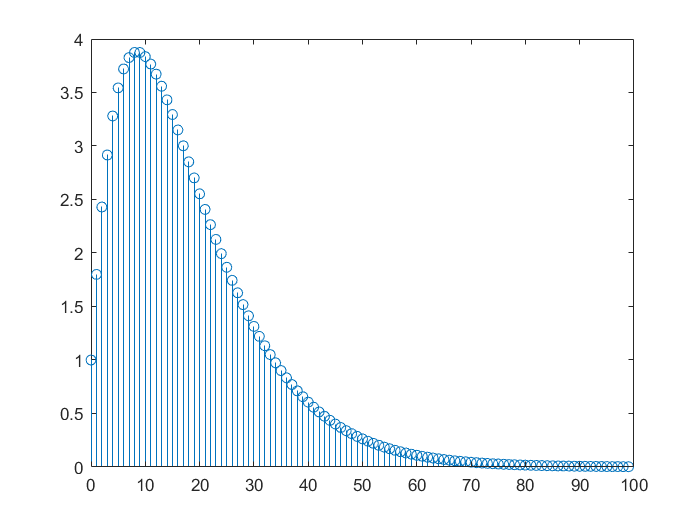

n=(0:99);
y=(n+1).*(0.9).^n;
stem(n,y);

### (b)

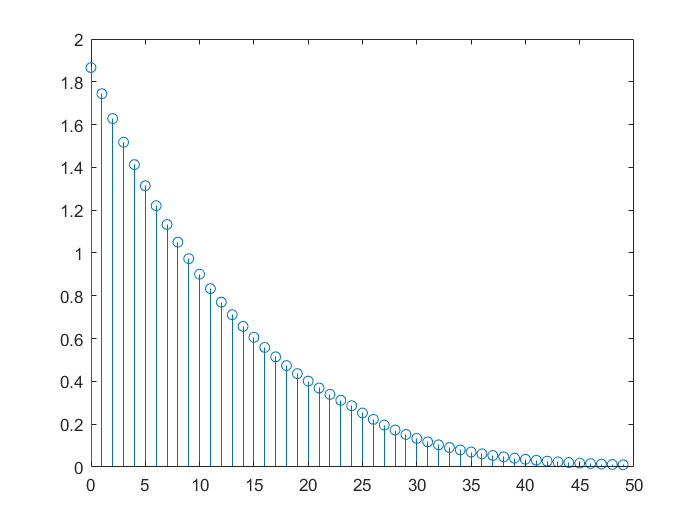

n=0:49;
x=(0.9).^n;
h=(0.9).^n;
stem(n,conv(x,h,"same"));

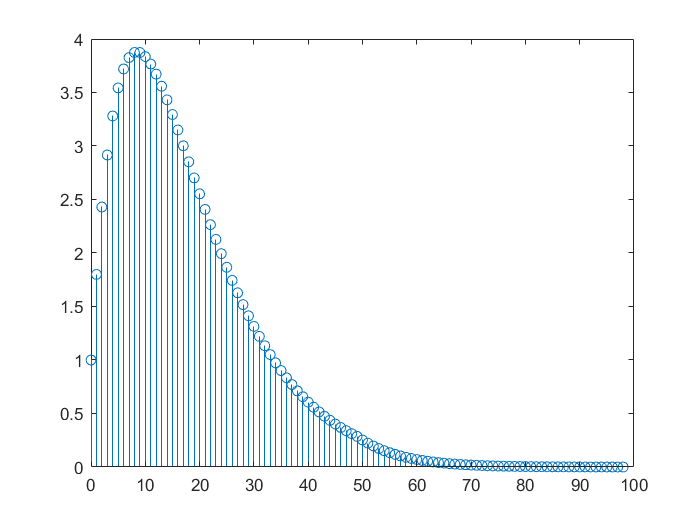

stem(0:98,conv(x,h,"full"));

### (c)

n=0:99;
x=(0.9).^n;
h=(0.9).^n;
stem(n,filter(h,1,x));

### (d)

The output in (c) is more close to that in (a) if conv in (b) is "same" version

since the ans of conv(x,h,"same") is central part of the convolution of the same size as x.

, the ans of conv(x,h,"full") is which we are familiar with

and the ans of filter(h,1,x) is given by $Y\left(z\right)=H\left(z\right)X\left(z\right)$

## P2

We have

 $A_x =\sum_{n=-\infty }^{\infty } x\left\lbrack n\right\rbrack$ and $y\left\lbrack n\right\rbrack =\sum_{k=-\infty }^{\infty } x\left\lbrack k\right\rbrack h\left\lbrack n-k\right\rbrack$

### (a)


$$A_y =\sum_{n=-\infty }^{\infty } y\left\lbrack n\right\rbrack =\sum_{n=-\infty }^{\infty } \sum_{k=-\infty }^{\infty } x\left\lbrack k\right\rbrack h\left\lbrack n-k\right\rbrack =\sum_{k=-\infty }^{\infty } \sum_{n=-\infty }^{\infty } x\left\lbrack k\right\rbrack h\left\lbrack n-k\right\rbrack =\sum_{k=-\infty }^{\infty } x\left\lbrack k\right\rbrack A_h =A_x A_h$$


### (b)

x=sin(2*pi*0.01*(0:100)) + 0.05*randn(1,101);
h_1=ones(1,5);
y_1=conv(x,h_1,"full");
A_y_1=sum(y_1);
A_xA_h_1=sum(x)*sum(h_1);

figure
subplot(2,1,1);
plot((0:100),x);
xlabel("n");
ylabel("x[n]");
subplot(2,1,2);
plot((0:104),y_1);
axis tight;
xlabel("n");
ylabel("y[n]");


### (c)

h_2=ones(1,5)/5;
y_2=conv(x,h_2,"full");
A_y_1

A_y_1 = 1.6213

A_xA_h_1

A_xA_h_1 = 1.6213

A_y_2=sum(y_2)

A_y_2 = 0.3243

A_xA_h_2=sum(x)*sum(h_2)

A_xA_h_2 = 0.3243

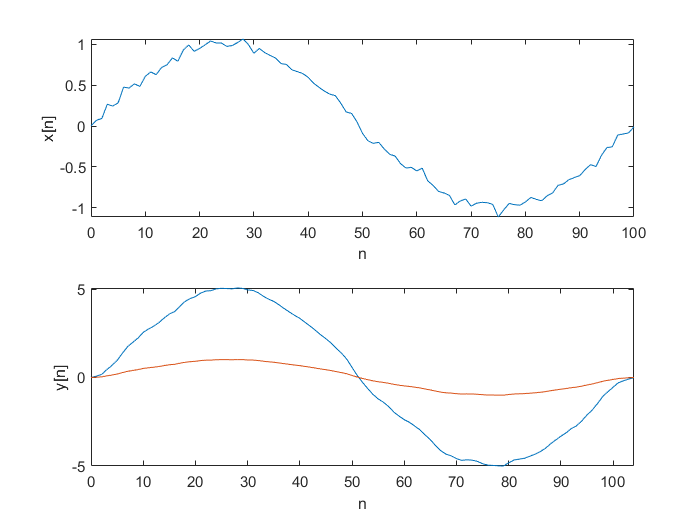

hold on
subplot(2,1,1);
plot((0:100),x);
xlabel("n");
ylabel("x[n]");
subplot(2,1,2);
plot((0:104),y_2);
axis tight;
xlabel("n");
ylabel("y[n]");

compare=y_1-y_2*5

compare = 	1.0e+-14 *

         0   -0.0014         0         0         0    0.0111   -0.0444   -0.0444   -0.0222         0         0         0         0    0.0444   -0.0444    0.0444   -0.0444    0.0888         0         0    0.0888   -0.0888   -0.0888         0         0         0   -0.0888         0    0.0888   -0.0888   -0.0888         0    0.0888         0         0         0         0   -0.0444   -0.0444         0         0   -0.0444         0         0         0         0   -0.0222   -0.0222         0         0


Note that in the graph of y[n], the blue curve is $y_1 \left\lbrack n\right\rbrack$ and the orange curve is $y_2 \left\lbrack n\right\rbrack$ 

Here use "hold on" instead of "figure" is easier to compare the difference between these to curve 

### (d)

$y_1 \left\lbrack n\right\rbrack$ is almost 5 times of $y_2 \left\lbrack n\right\rbrack$ which is easy to see by the compare array.

Otherwise , I think $y_1 \left\lbrack n\right\rbrack$ is exactly 5 times of $y_2 \left\lbrack n\right\rbrack$ ,and the entries of compare are not all zero due to truncation error.

## P3

### (a)


$$\delta \left\lbrack n\right\rbrack =u\left\lbrack n\right\rbrack -u\left\lbrack n-1\right\rbrack$$


Since the system is LTI , we can derive


$$h\left\lbrack n\right\rbrack =y\left\lbrack n\right\rbrack -y\left\lbrack n-1\right\rbrack =2{\left(\frac{1}{3}\right)}^n u\left\lbrack n\right\rbrack -2{\left(\frac{1}{3}\right)}^{n-1} u\left\lbrack n-1\right\rbrack$$


n=0:100;
x=delta(0,0,100)'

x =      1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y_1=2*(1/3).^n.*unitstep(0,0,100)';
h_1=2*(1/3).^n.*unitstep(0,0,100)'-2*(1/3).^(n-1).*unitstep(0,1,100)';
y_2=filter(h_1,1,unitstep(0,0,100)');
compare=y_1-y_2

compare = 	1.0e+-15 *

         0    0.1110    0.1110    0.0971    0.1076    0.0347    0.0859    0.1765    0.1328    0.0443    0.2368    0.2270    0.0757    0.0992    0.1071    0.1837    0.2093    0.2178    0.1466    0.1229    0.1150   -0.0357    0.1361    0.1194   -0.0342    0.1366    0.1196    0.0399    0.1613    0.0538    0.1660    0.1293    0.1911    0.1377    0.1199    0.0400    0.0133    0.0044    0.0015    0.0005    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


$y_1 \left\lbrack n\right\rbrack$ is almost equal $y_2 \left\lbrack n\right\rbrack$ which is easy to see by the compare array.

Otherwise , I think $y_1 \left\lbrack n\right\rbrack$ is exactly equal to  $y_2 \left\lbrack n\right\rbrack$ ,and the entries of compare are not all zero due to truncation error.

### (b)

$H\left(z\right)=2\left(\frac{1-z^{-1} }{1-3^{-1} z^{-1} }\right)$ has zero at $z=1$ , pole at $z=3^{-1}$

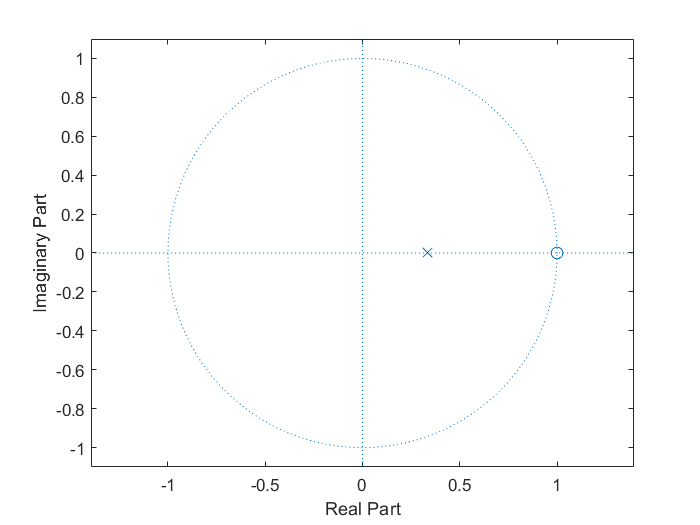

q=1;
p=1/3;
figure
zplane(q,p);

### (c)

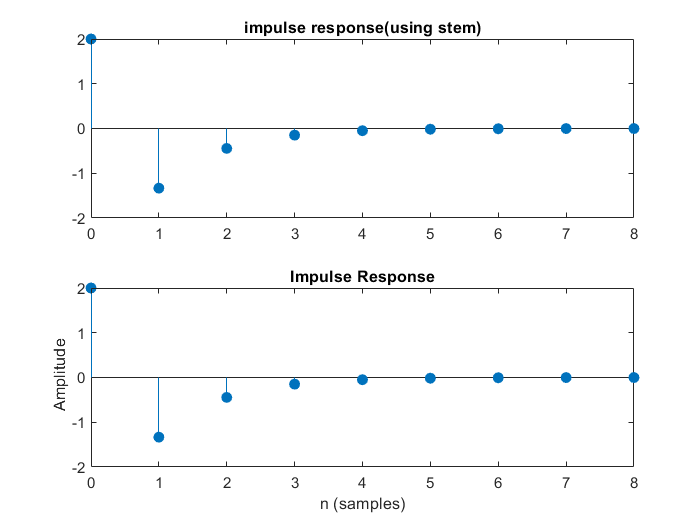

n=0:8;
x=delta(0,0,8)';
figure;
subplot(2,1,1);
stem(n,filter(h_1,1,x),"filled")
title("impulse response(using stem)");
subplot(2,1,2)
impz([2,-2],[1,-1/3]);

### (d)


$$H\left(z\right)=2\left(\frac{1-z^{-1} }{1-3^{-1} z^{-1} }\right)$$


[A,p,C]=residuez([2,-2],[1,-1/3])

A = -4

p = 0.3333

C = 6

We get $H\left(z\right)=6+\left(\frac{-4}{1-3^{-1} z^{-1} }\right)$

Thus , $h\left\lbrack n\right\rbrack =6\delta \left\lbrack n\right\rbrack -4{\left(3\right)}^{-n} u\left\lbrack n\right\rbrack$ since the system is causal

## P4

Consider the system is causal

$H\left(z\right)=\frac{b_0 +b_1 z^{-1} }{1+a_1 z^{-1} +a_2 z^{-2} }=\frac{b_0 +b_1 z^{-1} }{{\left(1+\frac{a_1 }{2}z^{-1} \right)}^2 }$  if it has equal poles i.e. $a_1 =2\sqrt{a_2 }$ 


$$\Rightarrow H\left(z\right)=\frac{\frac{b_0 a_1 -2b_1 }{a_1 }}{{\left(1+\frac{a_1 }{2}z^{-1} \right)}^2 }+\frac{\frac{2b_1 }{a_1 }}{1+\frac{a_1 }{2}z^{-1} }\iff h\left\lbrack n\right\rbrack =\frac{b_0 a_1 \left(n+1\right)-2b_1 n}{a_1 }{\left(\frac{-2}{a_1 }\right)}^n u\left\lbrack n\right\rbrack$$
 

Also we can view $H\left(z\right)$ as $\frac{d}{\textrm{dz}}\left(\frac{1}{1+\frac{a_1 }{2}z^{-1} }\right)\left(\frac{2b_0 }{a_1 }z^2 +\frac{2b_1 }{a_1 }z\right)$, thus ,  ROC of $H\left(z\right)$ is $\left|z\right|>\left|\frac{a_1 }{2}\right|$

### (a)

The system is stable $\textrm{iff}$ ROC of $H\left(z\right)$ contains unit circle

$\Rightarrow$This system is stable if ${\left|a\right.}_1 \left|>2\right.$ , else it is not stable

### (b)

h=@(a,n,b_0,b_1) (b_0.*a.*(n+1)-2.*b_1.*n)/a.*(-2/a).^n

h = function_handle with value:
    @(a,n,b_0,b_1)(b_0.*a.*(n+1)-2.*b_1.*n)/a.*(-2/a).^n


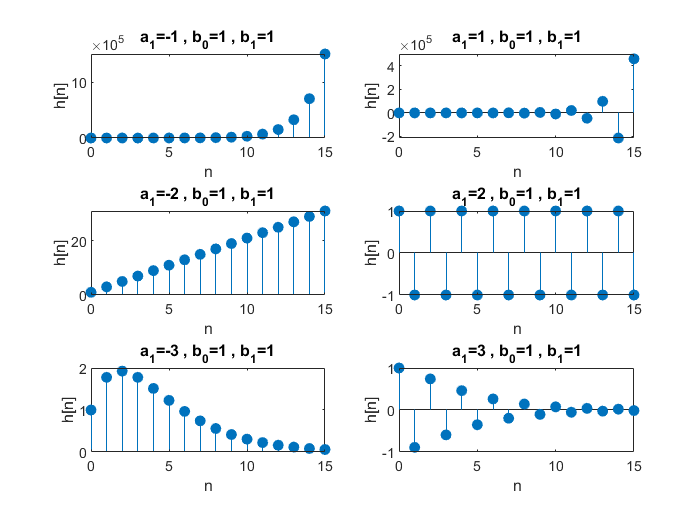

n=0:15;
figure
subplot(3,2,1)
    stem(n,h(-1,n,1,1),"filled")
    title("a_1=-1 , b_0=1 , b_1=1")
    xlabel("n")
    ylabel("h[n]")
subplot(3,2,2)
    stem(n,h(1,n,1,1),"filled")
    title("a_1=1 , b_0=1 , b_1=1")
    xlabel("n")
    ylabel("h[n]")
subplot(3,2,3)
    stem(n,h(-2,n,1,1),"filled")
    title("a_1=-2 , b_0=1 , b_1=1")
    xlabel("n")
    ylabel("h[n]")
subplot(3,2,4)
    stem(n,h(2,n,1,1),"filled")
    title("a_1=2 , b_0=1 , b_1=1")
    xlabel("n")
    ylabel("h[n]")
subplot(3,2,5)
    stem(n,h(-3,n,1,1),"filled")
    title("a_1=-3 , b_0=1 , b_1=1")
    xlabel("n")
    ylabel("h[n]")
subplot(3,2,6)
    stem(n,h(3,n,1,1),"filled")
    title("a_1=3 , b_0=1 , b_1=1")
    xlabel("n")
    ylabel("h[n]")

## P5

### (a)

$y\left\lbrack n\right\rbrack =2\cos \left(\omega_0 \right)y\left\lbrack n-1\right\rbrack -y\left\lbrack n-2\right\rbrack$ with $y\left\lbrack -1\right\rbrack =0\;,y\left\lbrack -2\right\rbrack =-\textrm{Asin}\left(\omega_0 \right)$


$$\begin{array}{l}
\textrm{Claim}\;:\;y\left\lbrack n\right\rbrack =\textrm{Asin}\left({\left(n+1\right)\omega }_0 \right)\;\textrm{for}\;n\ge 0\\
\textrm{For}\;n=0\\
y\left\lbrack 0\right\rbrack =2\cos \left(\omega_0 \right)y\left\lbrack -1\right\rbrack -y\left\lbrack -2\right\rbrack =\textrm{Asin}\left(\omega_0 \right)\;\;,\;\textrm{true}\\
\textrm{For}\;n=1\\
y\left\lbrack 1\right\rbrack =2\cos \left(\omega_0 \right)y\left\lbrack 0\right\rbrack -y\left\lbrack -1\right\rbrack =2A\cos \left(\omega_0 \right)\sin \left(\omega_0 \right)=\sin \left(2\omega_0 \right)\;,\textrm{true}\\
\textrm{Assume}\;\textrm{the}\;\textrm{statement}\;\textrm{is}\;\textrm{true}\;\textrm{for}\;n=k-1,k-2,\textrm{then}\\
y\left\lbrack k\right\rbrack =2\cos \left(\omega_0 \right)y\left\lbrack k-1\right\rbrack -y\left\lbrack k-2\right\rbrack =2A\cos \left(\omega_0 \right)\sin \left(k\omega_0 \right)-\textrm{Asin}\left({\left(k-1\right)\omega }_0 \right)\\
=2A\cos \left(\omega_0 \right)\sin \left(k\omega_0 \right)-\textrm{Asin}\left(k\omega_0 \right)\cos \left(\omega_0 \right)+\textrm{Asin}\left(\omega_0 \right)\cos \left({k\omega }_0 \right)\\
=A\cos \left(\omega_0 \right)\sin \left(k\omega_0 \right)+\textrm{Asin}\left(\omega_0 \right)\cos \left({k\omega }_0 \right)\\
=\textrm{Asin}\left({\left(k+1\right)\omega }_0 \right)\;,\textrm{true}\\
\textrm{By}\;\textrm{mathematical}\;\textrm{induction}\;y\left\lbrack n\right\rbrack =\textrm{Asin}\left({\left(n+1\right)\omega }_0 \right)\;\textrm{for}\;n\ge 0\;\;i\ldotp e\ldotp y\left\lbrack n\right\rbrack =\textrm{Asin}\left({\left(n+1\right)\omega }_0 \right)u\left\lbrack n\right\rbrack 
\end{array}$$


### (b)

n=0:99

n =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49


w=0.1*pi;
a=[1,-2*cos(w),1];
b=[0,0,0];
yic=[0,-2*sin(w)];
xic=[0,0];
zic=filtic(b,a,yic,xic);
y_1=2*sin((n+1)*w);
y_2=filter(b,a,zeros(1,100),zic);
compare=y_1-y_2

compare = 	1.0e+-13 *

         0    0.0022    0.0044    0.0044    0.0089    0.0155    0.0222    0.0311    0.0366    0.0402    0.0400    0.0355    0.0289    0.0178    0.0044   -0.0111   -0.0289   -0.0466   -0.0566   -0.0626   -0.0622   -0.0555   -0.0400   -0.0178    0.0044    0.0289    0.0511    0.0688    0.0822    0.0873    0.0844    0.0733    0.0533    0.0311    0.0044   -0.0244   -0.0488   -0.0688   -0.0844   -0.0920   -0.0910   -0.0822   -0.0644   -0.0377   -0.0044    0.0311    0.0644    0.0910    0.1132    0.1233


The outputs of y_1 and y_2 are almost the same , and the negligible difference between these outputs may be due to truncation error

## P6

### (a)

x=rand(1,8);
compare=dtfs0(x)-dtfs(x)

compare = 	1.0e+-15 *

   0.1110 + 0.0000i  -0.0208 + 0.0278i  -0.0139 - 0.0278i  -0.0486 + 0.0971i   0.0139 - 0.0426i  -0.1735 - 0.1388i  -0.3678 - 0.0833i   0.3331 + 0.0278i


x is a random 1X8 array

The outputs of dtfs0 and dtfs are almost the same , and the negligible difference between these outputs may be due to truncation error

### (b)

c=rand(1,8);
compare=idtfs0(c)-idtfs(c)

compare = 	1.0e+-14 *

   0.0444 + 0.0000i  -0.0139 - 0.0028i   0.0000 + 0.0361i   0.0278 - 0.0222i   0.0000 - 0.0412i  -0.2442 - 0.0333i  -0.0222 + 0.1082i  -0.0305 + 0.0194i


 c is a random 1X8 array

The outputs of dtfs0 and dtfs are almost the same , and the negligible difference between these outputs may be due to truncation error

## P7

### (a)

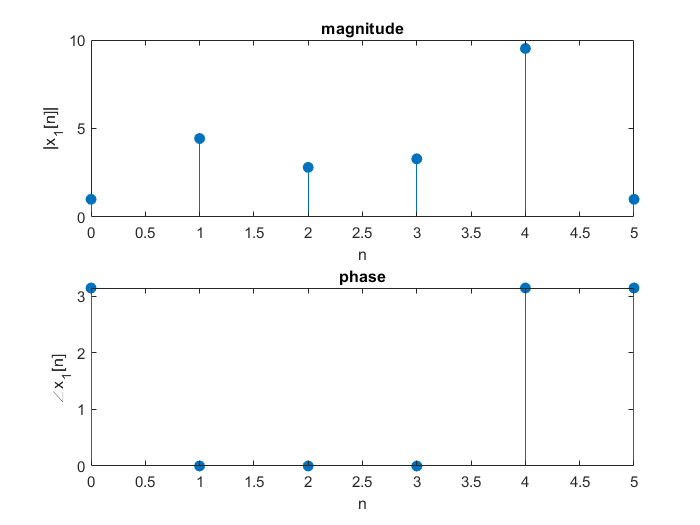

n=0:5;
x_1=4*cos(1.2*pi*n+pi/3)+6*sin(0.4*pi*n-pi/6);
figure
subplot(2,1,1)
   stem(n,abs(x_1),"filled") 
   title("magnitude")
   xlabel("n")
   ylabel("|x_1[n]|")
subplot(2,1,2)
   stem(n,angle(x_1),"filled")
   title("phase")
   xlabel("n")
   ylabel("∠x_1[n] ")

### (b)

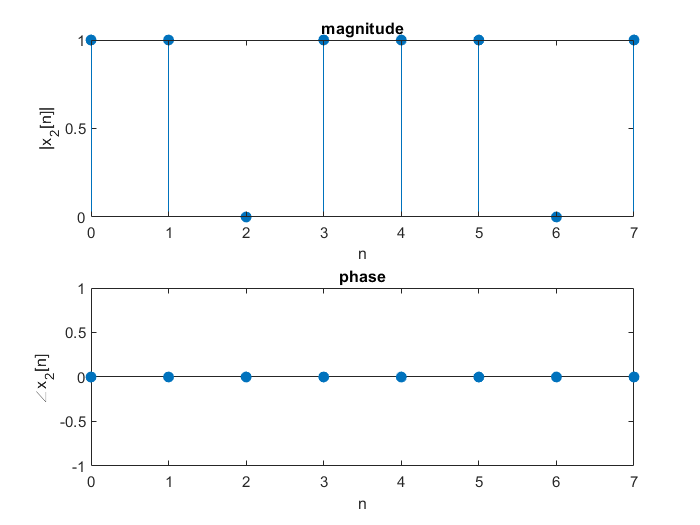

n=0:7;
x_2=[1,1,0,1,1,1,0,1];
figure
subplot(2,1,1)
   stem(n,abs(x_2),"filled") 
   title("magnitude")
   xlabel("n")
   ylabel("|x_2[n]|")
subplot(2,1,2)
   stem(n,angle(x_2),"filled")
   title("phase")
   xlabel("n")
   ylabel("∠x_2[n] ")

### (c)

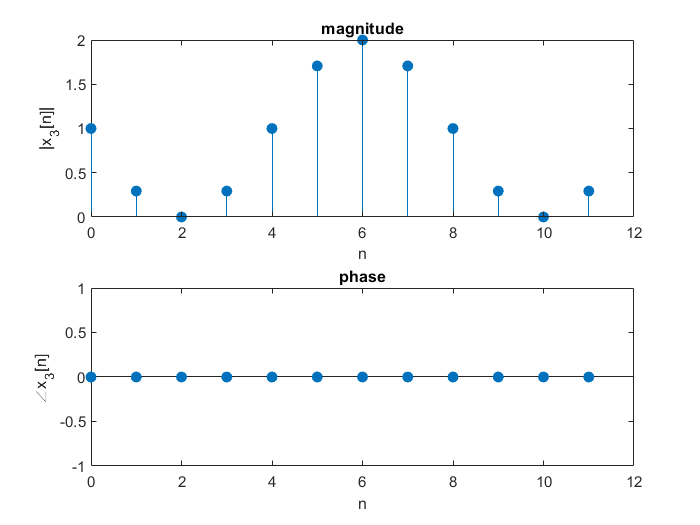

n=0:11;
x_3=1-sin(pi*n/4);
figure
subplot(2,1,1)
   stem(n,abs(x_3),"filled") 
   title("magnitude")
   xlabel("n")
   ylabel("|x_3[n]|")
subplot(2,1,2)
   stem(n,angle(x_3),"filled")
   title("phase")
   xlabel("n")
   ylabel("∠x_3[n] ")

## P8

### (a)

x=[1 1 1]; % n=-1,0,1 
om=linspace(-pi, pi, 60); 
X1=dtft12(x, -1, om);
X2=freqz(x, 1, om)

X2 =    1.0000 - 0.0000i   0.9831 - 0.1051i   0.9332 - 0.2018i   0.8533 - 0.2823i   0.7479 - 0.3394i   0.6230 - 0.3671i   0.4860 - 0.3611i   0.3450 - 0.3185i   0.2088 - 0.2386i   0.0860 - 0.1224i  -0.0150 + 0.0270i  -0.0865 + 0.2049i  -0.1220 + 0.4046i  -0.1166 + 0.6185i  -0.0671 + 0.8377i   0.0280 + 1.0529i   0.1680 + 1.2543i   0.3500 + 1.4325i   0.5694 + 1.5789i   0.8198 + 1.6859i   1.0931 + 1.7470i   1.3802 + 1.7580i   1.6710 + 1.7161i   1.9551 + 1.6209i   2.2221 + 1.4741i   2.4621 + 1.2794i   2.6661 + 1.0425i   2.8263 + 0.7708i   2.9367 + 0.4731i   2.9929 + 0.1595i   2.9929 - 0.1595i   2.9367 - 0.4731i   2.8263 - 0.7708i   2.6661 - 1.0425i   2.4621 - 1.2794i   2.2221 - 1.4741i   1.9551 - 1.6209i   1.6710 - 1.7161i   1.3802 - 1.7580i   1.0931 - 1.7470i   0.8198 - 1.6859i   0.5694 - 1.5789i   0.3500 - 1.4325i   0.1680 - 1.2543i   0.0280 - 1.0529i  -0.0671 - 0.8377i  -0.1166 - 0.6185i  -0.1220 - 0.4046i  -0.0865 - 0.2049i  -0.0150 - 0.0270i


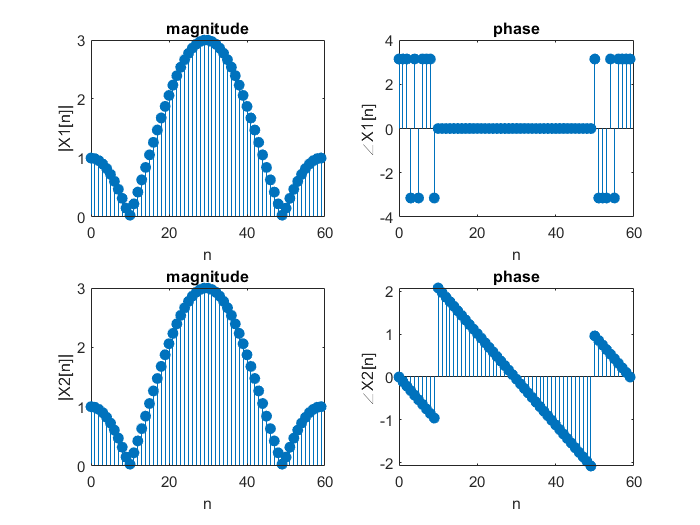

n=0:59;
figure
subplot(2,2,1)
   stem(n,abs(X1),"filled") 
   title("magnitude")
   xlabel("n")
   ylabel("|X1[n]|")
subplot(2,2,2)
   stem(n,angle(X1),"filled")
   title("phase")
   xlabel("n")
   ylabel("∠X1[n] ")
subplot(2,2,3)
   stem(n,abs(X2),"filled") 
   title("magnitude")
   xlabel("n")
   ylabel("|X2[n]|")
subplot(2,2,4)
   stem(n,angle(X2),"filled")
   title("phase")
   xlabel("n")
   ylabel("∠X2[n] ")   

### (b)

The magnitude is the same ,but the phase is different

Since what the function dtft12(x,-1,om) doing is

 
$$\begin{array}{l}
X=\textrm{freqz}\left(x,1,\textrm{om}\right);\\
X=e^{j*\textrm{om}\left\lbrack n\right\rbrack } 
\end{array}$$


It rotates X[n] by multipling $e^{j*\textrm{om}\left\lbrack n\right\rbrack }$

## P9

   
   img = imread('DSP.png'); 
   figure
   subplot(2,3,1)
   imshow(img); 
   imwrite(img, 'DSP0.png'); 

### (a)

h_1=ones(5,5)/25;
img_1=conv2(img,h_1);
subplot(2,3,2)
    imshow(double(img_1));

The curve of this image is narrower

### (b)

h_2=[1,0,-1;2,0,-2;1,0,-1];
h_3=[1,2,1;0,0,0;-1,-2,-1];
img_2=conv2(img,h_2);
img_3=conv2(img,h_3);
subplot(2,3,3)
    imshow(abs(uint8(img_2)));
subplot(2,3,4)
    imshow(abs(uint8(img_3)));

The white curve is appear on the right side of the character of the img_2

The white curve is appear below the character of the imh_3

### (c)

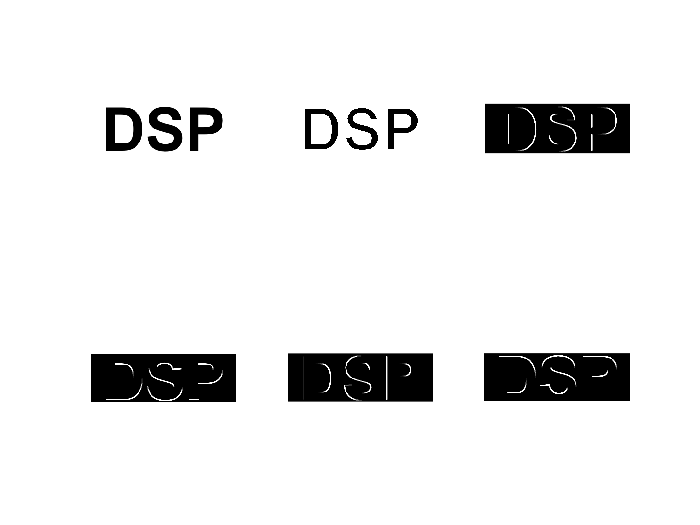

img_4=filter2(h_2,img);
img_5=filter2(h_3,img);
subplot(2,3,5)
    imshow(abs(uint8(img_4)));
subplot(2,3,6)
    imshow(abs(uint8(img_5)));

The white curve is appear on the left side of the character of the img_4

The white curve is appear above the character of the img_5

The difference between conv2 and filter2 is that each output is -1 time of the other

(if we discard the first and last columns and rows of the output of conv)

## P10

   [y,Fs] = audioread('handel.wav'); 
   playerObj = audioplayer(y, Fs); 
  % play(playerObj); 
   audiowrite('handel0.wav', y, Fs); 

### (a)

   N=length(y);
   y_1=y(2:2:N);
  % sound(y_1,Fs/2);

### (b)

   y_2=y(2:8:N);
   %sound(y_2,Fs/8);

### (c)

The sound is fuzzier as reducing the sample rate